functions from:

Glover, D. M., Doney, S. C., & Jenkins, W. J. (Eds.). (2011). Least squares and regression techniques, goodness of fit and tests, and nonlinear least squares techniques. In *Modeling Methods for Marine Science *(pp. 49–74). Cambridge University Press; Cambridge Core. https://doi.org/10.1017/CBO9780511975721.004 

code written by Sarah Lang

% Set Up
clear
clc
close all 

cd '/Users/sarahlang/Desktop/lmnonlinear/' % Change for your system

% Add Functions and data to Path 
addpath('/Users/sarahlang/Desktop/lmnonlinear/functions/')
addpath('/Users/sarahlang/Desktop/lmnonlinear/data/')

%define vars, write to .dat for future use

%Kd_min, Rrs_max, and in situ secchi depth for use in LMA
readtable("landsat8only.csv")

ans = 84×3 table
     Var1        Var2      Var3
    _______    ________    ____

    0.93204    0.012286     0.5
    0.44428    0.013437     0.9
    0.37066    0.011876     1.1
    0.67026    0.016317    0.65
    0.63729    0.017053    0.69
    0.56288    0.016064    0.65
     0.5627    0.015491       1
    0.61967    0.017038    0.75
    0.48231    0.016724    0.95
    0.56018     0.01723    0.57
    0.53973    0.011856    1.05
    0.95469    0.019392     0.6
     1.0343    0.017959    0.55
     1.0104    0.018352     0.6
     0.5599    0.014189    0.65
    0.93614    0.017017    1.15


writetable(ans,"lml8.dat",'WriteVariableNames',0)

readtable("sentinel2only.csv")
writetable(ans,"lms2.dat",'WriteVariableNames',0)

%Satellite Secchi depths from Lee et al., 2016 and in situ values. For
%comparing to new values from adjustment via Levenburg-Marquardt
readtable("leelandsatsecchi.csv")

ans = 84×2 table
     Var1      Var2
    _______    ____

    0.98058     0.5
     2.0506     0.9
     2.4741     1.1
     1.3524    0.65
     1.4119    0.69
     1.6361    0.65
     1.6182       1
     1.4562    0.75
     1.8938    0.95
     1.6074    0.57
     1.6999    1.05
    0.93353     0.6
    0.86611    0.55
    0.88548     0.6
     1.6661    0.65
    0.96051    1.15


writetable(ans,"l8secchi.dat",'WriteVariableNames',0)

readtable("leesentinelsecchi.csv")

ans = 32×2 table
     Var1     Var2
    ______    ____

    2.4684    0.75
    1.8915    1.52
     2.354    1.09
     1.837    0.97
    2.9498     1.6
    1.5904    0.55
    1.2414     0.8
    1.2756     0.9
    1.4103    0.45
    3.2803    1.25
    2.4871    1.05
    2.5135    1.15
    2.1254     0.7
    1.2791    0.45
    2.1415    0.73
    1.2862    0.45


writetable(ans,"s2secchi.dat",'WriteVariableNames',0)


ans = 32×3 table
     Var1        Var2      Var3
    _______    ________    ____

    0.37514    0.014153    0.75
     0.4817    0.014233    1.52
    0.38829    0.012833    1.09
    0.49479    0.014112    0.97
    0.30939    0.014294     1.6
    0.56818    0.015691    0.55
    0.72921    0.015068     0.8
    0.71228    0.016026     0.9
    0.64334    0.015796    0.45
    0.27738    0.014362    1.25
    0.36619    0.015018    1.05
    0.36169     0.01491    1.15
    0.42525    0.016041     0.7
    0.71524    0.012468    0.45
    0.42493    0.014791    0.73
    0.70995    0.012961    0.45


Landsat-8 Data

load lml8.dat;
kdmin=lml8(:,1); %mean minimum Kd value, x1
maxrrs=lml8(:,2); %mean max Rrs value, x2
secchi=lml8(:,3); %in situ secchi depth, y
load l8secchi.dat;
leesecchi=l8secchi(:,1);
insitusecchi=l8secchi(:,2);
load s2secchi.dat;
leesecchis2=s2secchi(:,1);
insitusecchis2=s2secchi(:,2);

Sentinel-2 Data (denoted with a "2")

load lms2.dat;
kdmin2=lms2(:,1); %mean minimum Kd value, x1
maxrrs2=lms2(:,2); %mean max Rrs value, x2
secchi2=lms2(:,3); %in situ secchi depth, y

figure(1)
plot(kdmin2,secchi2,'b.')

Undefined function or variable 'kdmin2'.

xlabel('kdmin')
ylabel('Secchi depth (m)')
figure(2)
plot(maxrrs2,secchi2,'r.')
xlabel('maxrrs')
ylabel('Secchi depth (m)')
figure(3)
plot(maxrrs2,kdmin2,'r.')
xlabel('maxrrs')
ylabel('kdmin')

corrcoef(kdmin,secchi)

ans =     1.0000   -0.3883
   -0.3883    1.0000


corrcoef(maxrrs,secchi)

ans =     1.0000   -0.0999
   -0.0999    1.0000


corrcoef(maxrrs,kdmin)

ans =     1.0000    0.1884
    0.1884    1.0000


%mod=

ans = Generalized linear regression model:
    y ~ 1 + x1
    Distribution = Normal

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)      1.0101    0.076282     13.241    4.5831e-22
    x1             -0.40234     0.10545    -3.8155    0.00026249


84 observations, 82 error degrees of freedom
Estimated Dispersion: 0.0496
F-statistic vs. constant model: 14.6, p-value = 0.000262

help nlleasqr

 function[f,p,kvg,iter,corp,covp,covr,stdresid,Z,r2]=
                    nlleasqr(x,y,pin,{func,stol,niter,wt,dp,dfdp,options})
 
  Version 3.beta
  Levenberg-Marquardt nonlinear regression of f(x,p) to y(x), where:
  x=vec or mat of indep variables, 1 row/observation: x=[x0 x1....xm]
  y=vec of obs values, same no. of rows as x.
  wt=vec(dim=1 or length(x)) of statistical weights.  These should be set
    to be proportional to (sqrts of var(y))^-1; (That is, the covaraince
    matrix of the data is assumed to be proportional to diagonal with diagonal
    equal to (wt.^2)^-1.  The constant of proportionality will be estimated.),
    default=1.
  pin=vector of initial parameters to be adjusted by leasqr.
  dp=fractional incr of p for numerical partials,default= .001*ones(size(pin))
    dp(j)>0 means central differences.
    dp(j)<0 means one-sided differences.
  Note: dp(j)=0 holds p(j) fixed i.e. leasqr wont change initial guess: pin(j)
  func=name of function in quotes,of the form y=

%assign independent vars x1 and x2 to vec, landsat-8
xl8=[kdmin(:),maxrrs(:)];
yl8=secchi;

%assign independent vars x1 and x2 to vec, sentinel-2
xs2=[kdmin2(:),maxrrs2(:)];
ys2=secchi2;

Landsat-8 modeling- do one at a time because parameters from algo named the same

%ain=[2.5 0.14 0.013]; %initial parameter guess
%ain=[1 0.1 0.01];
ain=[1 0.1 0.01];
[f,a,kvg,iter,corp,covp,covr,stdresid,Z,r2]= nlleasqr(xl8,yl8,ain,'modfunc');

Sentinel-2 modeling

%ain=[2.5 0.14 0.013]; %initial parameter guess
%ain=[1 0.1 0.01];
x2=[kdmin2(:),maxrrs2(:)];
y2=secchi2;
ain=[2.1 0.1 0.01]; %won't converge if you don't have a good first guess
[f,a,kvg,iter,corp,covp,covr,stdresid,Z,r2]= nlleasqr(x2,y2,ain,'modfunc');

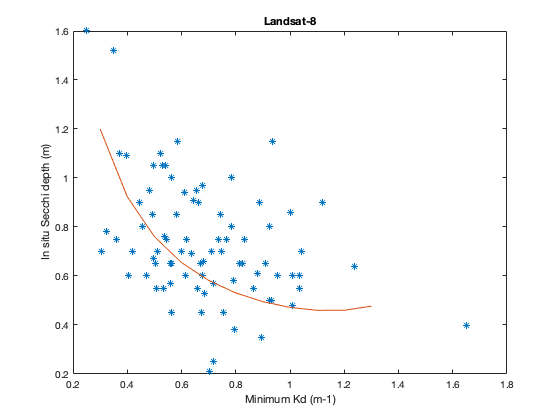

%for landsat 
xfk=[0.3:.1:1.3]; % dummy array to plot
xfr=[0.0113:0.0008:0.02];
%for sentinel
%xfk=[0.2:.1:1.1]; % dummy array to plot
%xfr=[0.0114:0.0005:0.016];
xf=[xfk(:),xfr(:)];
yf=modfunc(xf,a); % compute fit for the dummy array

figure(4)
plot(xl8(:,1),yl8,'*',xf(:,1),yf) % plot both data and fit on same graph
%title('Sentinel-2')
title('Landsat-8')
xlabel('Minimum Kd (m-1)')
ylabel('In situ Secchi depth (m)')

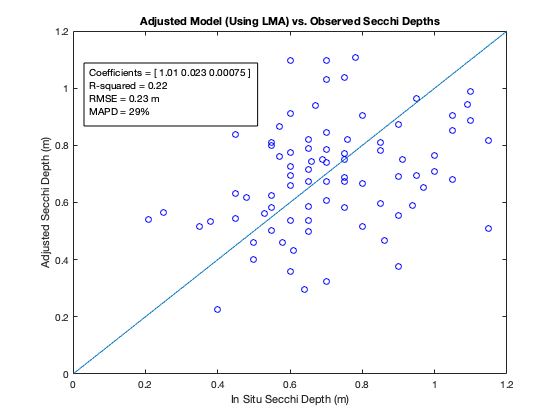

%landsat8 graph
ymodl8=modfunc(xl8,a);

MAPE_l8LMA=mean(abs(ymodl8-yl8)./yl8);
RMSE_l8LMA=sqrt(mean((yl8-ymodl8).^2));

figure(5)
plot(yl8,ymodl8,'bo')
title('Adjusted Model (Using LMA) vs. Observed Secchi Depths')
xlabel('In Situ Secchi Depth (m)')
ylabel('Adjusted Secchi Depth (m)')
ylim([0 1.2])
xlim([0 1.2])
annotation('textbox','String',"Coefficients = [ 1.01 0.023 0.00075 ] R-squared = 0.22                       RMSE = 0.23 m                             MAPD = 29%",'Position', [0.15 0.7 0.31 0.15])
hold on
refline(1,0)
hold off

print(gcf, 'landsat8LMA.pdf','-dpdf','-r300');


corrcoef(yl8,ymodl8)

ans =     1.0000    0.4732
    0.4732    1.0000


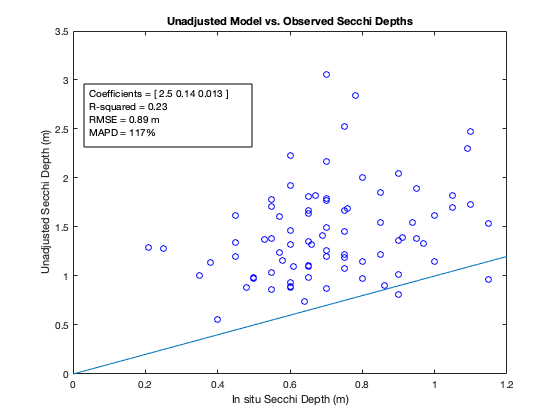

%landsat graph2
MAPE_l8lee=mean(abs(leesecchi-insitusecchi)./insitusecchi);
RMSE_l8lee=sqrt(mean((insitusecchi-leesecchi).^2));

figure(6)
plot(insitusecchi,leesecchi,'bo')
title('Unadjusted Model vs. Observed Secchi Depths')
xlabel('In situ Secchi Depth (m)')
ylabel('Unadjusted Secchi Depth (m)')
%ylim([0 1.2])
xlim([0 1.2])
annotation('textbox','String',"Coefficients = [ 2.5 0.14 0.013 ] R-squared = 0.23                       RMSE = 0.89 m                             MAPD = 117%",'Position', [0.15 0.65 0.3 0.15])
hold on;
refline(1,0);
hold off;
print(gcf, 'landsat8lee.pdf','-dpdf');


corrcoef(insitusecchi,leesecchi)

ans =     1.0000    0.4757
    0.4757    1.0000


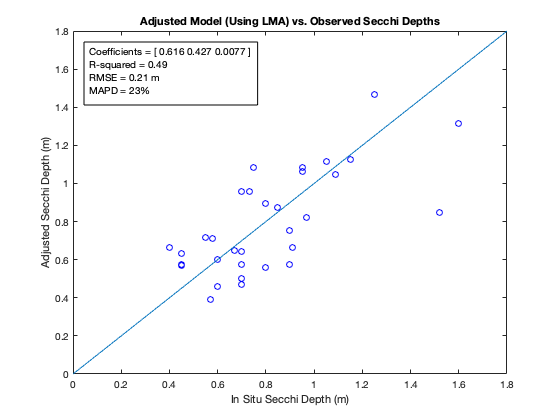

%sentinel2 graph

ymods2=modfunc(xs2,a);

MAPE_s2LMA=mean(abs(ymods2-ys2)./ys2);
RMSE_s2LMA=sqrt(mean((ys2-ymods2).^2));

figure(5)
plot(ys2,ymods2,'bo')
title('Adjusted Model (Using LMA) vs. Observed Secchi Depths')
xlabel('In Situ Secchi Depth (m)')
ylabel('Adjusted Secchi Depth (m)')
ylim([0 1.8])
xlim([0 1.8])
annotation('textbox','String',"Coefficients = [ 0.616 0.427 0.0077 ] R-squared = 0.49                       RMSE = 0.21 m                             MAPD = 23%",'Position', [0.15 0.75 0.31 0.15])
hold on
refline(1,0)
hold off

print(gcf, 'sentinel2LMA.pdf','-dpdf','-r300');


corrcoef(ys2,ymods2)

ans =     1.0000    0.6966
    0.6966    1.0000


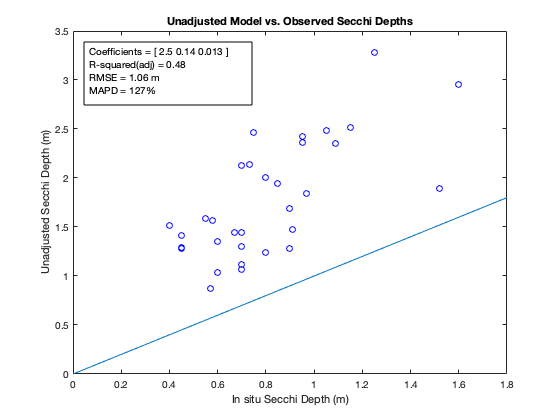

%sentinel graph2
MAPE_s2lee=mean(abs(leesecchis2-insitusecchis2)./insitusecchis2);
RMSE_s2lee=sqrt(mean((insitusecchis2-leesecchis2).^2));

figure(6)
plot(insitusecchis2,leesecchis2,'bo')
title('Unadjusted Model vs. Observed Secchi Depths')
xlabel('In situ Secchi Depth (m)')
ylabel('Unadjusted Secchi Depth (m)')
%ylim([0 3])
xlim([0 1.8])
annotation('textbox','String',"Coefficients = [ 2.5 0.14 0.013 ] R-squared(adj) = 0.48                  RMSE = 1.06 m                             MAPD = 127%",'Position', [0.15 0.75 0.3 0.15])
hold on;
refline(1,0);
hold off;
print(gcf, 'sentinel2lee.pdf','-dpdf');


corrcoef(insitusecchis2,leesecchis2)

ans =     1.0000    0.6946
    0.6946    1.0000
